问题一

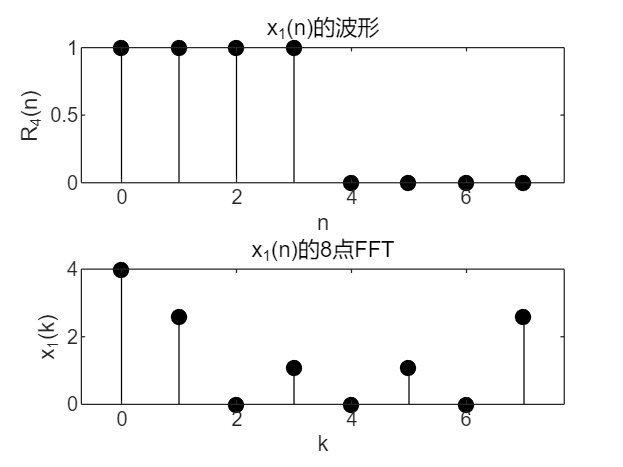

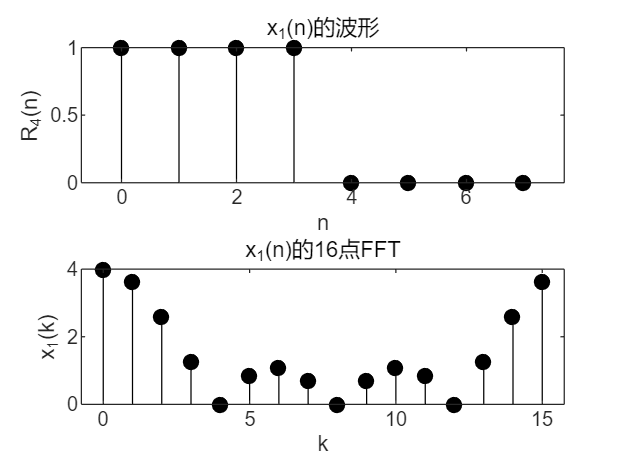

% --- 1. 定义序列 ---
n=0:7; % 定义时间索引 n (0 到 7)

% 假设 uDT 是单位阶跃函数，
% x1 = [1, 1, 1, 1, 0, 0, 0, 0]
% 这是一个长度为 8，前 4 个点为 1 的矩形序列。
x1=uDT(n)-uDT(n-4);
% --- 2. 计算 FFT ---
% 计算 x1 的 8 点 FFT (N=8，序列长度=8，不补零)
xk_1=fft(x1,8);
% 计算 x1 的 16 点 FFT (N=16，序列长度=8，自动在末尾补 8 个零)
% 补零可以使频域采样更密，频谱曲线更精细。
xk_2=fft(x1,16);
% --- 3. 绘图 (8点FFT) ---
figure(); % 新建一个图窗
% 上半图：绘制原始序列 x1(n)
subplot(211);
stem(n,x1,'fill','k');
title('x_1(n)的波形'),xlabel('n'),ylabel('R_4(n)');
% 下半图：绘制 8 点 FFT 的幅度 |xk_1(k)|
subplot(212);
stem(n,abs(xk_1),'fill','k');
title('x_1(n)的8点FFT'),xlabel('k'),ylabel('x_1(k)');
% --- 4. 绘图 (16点FFT) ---
figure(); % 新建第二个图窗
% 上半图：再次绘制原始序列 x1(n)
subplot(211);
stem(n,x1,'fill','k');
title('x_1(n)的波形'),xlabel('n'),ylabel('R_4(n)');
% 下半图：绘制 16 点 FFT 的幅度 |xk_2(k)| (k=0到15)
subplot(212);
stem(0:15,abs(xk_2),'fill','k');
title('x_1(n)的16点FFT'),xlabel('k'),ylabel('x_1(k)');

问题二

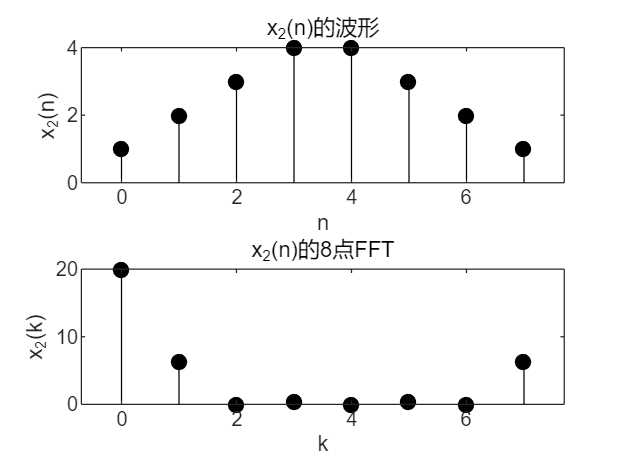

%问题二
x2=[1,2,3,4,4,3,2,1];
xk2_1=fft(x2,8);
xk2_2=fft(x2,16);
figure();
subplot(211);
stem(0:length(x2)-1,x2,'fill','k');
title('x_2(n)的波形'),xlabel('n'),ylabel('x_2(n)');
subplot(212);
stem(0:7,abs(xk2_1),'fill','k');
title('x_2(n)的8点FFT'),xlabel('k'),ylabel('x_2(k)');

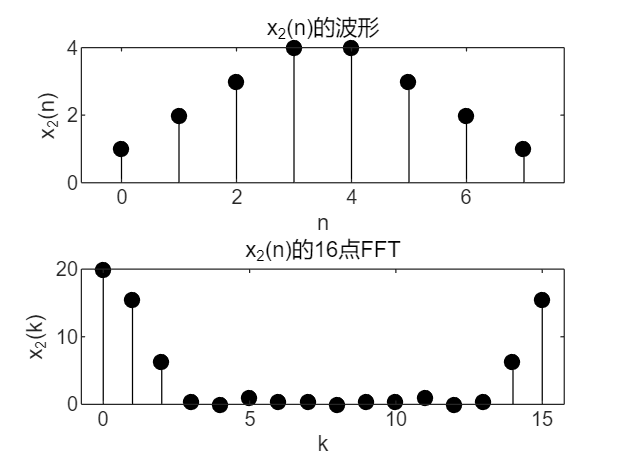

figure();
subplot(211);
stem(0:length(x2)-1,x2,'fill','k');
title('x_2(n)的波形'),xlabel('n'),ylabel('x_2(n)');
subplot(212);
stem(0:15,abs(xk2_2),'fill','k');
title('x_2(n)的16点FFT'),xlabel('k'),ylabel('x_2(k)');

问题三

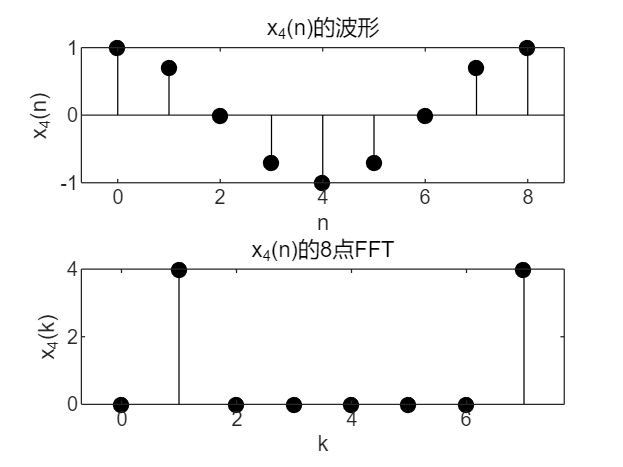

%问题三
n1=0:8;
n2=0:16;
x4_1=cos((pi./4).*n1);
x4_2=cos((pi./4).*n2);
xk4_1 = fft(x4_1,8);
xk4_2 = fft(x4_2,16);
figure();
subplot(211);
stem(0:length(n1)-1,x4_1,'fill','k');
title('x_4(n)的波形'),xlabel('n'),ylabel('x_4(n)');
subplot(212);
stem(0:7,abs(xk4_1),'fill','k');
title('x_4(n)的8点FFT'),xlabel('k'),ylabel('x_4(k)');

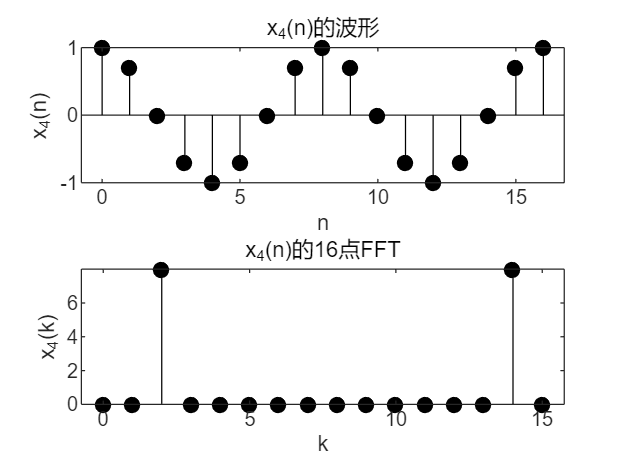

figure();
subplot(211);
stem(0:length(n2)-1,x4_2,'fill','k');
title('x_4(n)的波形'),xlabel('n'),ylabel('x_4(n)');
subplot(212);
stem(0:15,abs(xk4_2),'fill','k');
title('x_4(n)的16点FFT'),xlabel('k'),ylabel('x_4(k)');

问题四

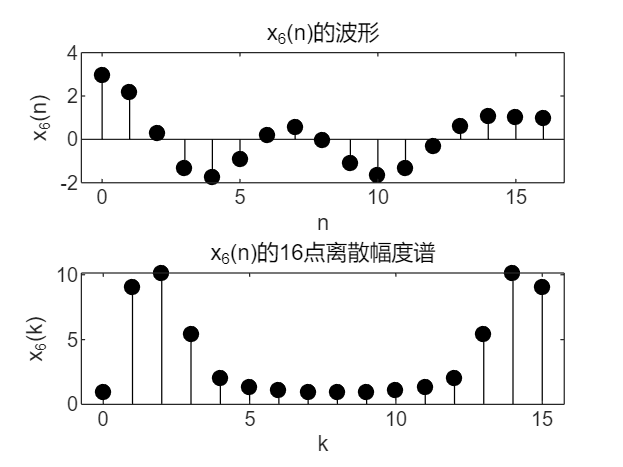

%问题四
fs = 64;
T = 1./fs;
n = 0:fs;
n1 = 0:16;n2 = 0:32;
xnT=cos(8.*pi.*n.*T)+cos(16.*pi.*n.*T)+cos(20.*pi.*n.*T);
xnT1=cos(8.*pi.*n1.*T)+cos(16.*pi.*n1.*T)+cos(20.*pi.*n1.*T);
xnT2=cos(8.*pi.*n2.*T)+cos(16.*pi.*n2.*T)+cos(20.*pi.*n2.*T);
N1 = 16;N2 = 32;N3 = 64;
xk1=fft(xnT,N1);xk2=fft(xnT,N2);xk3=fft(xnT,N3);
figure();
subplot(211);stem(0:length(xnT1)-1,xnT1,'fill','k');
title('x_6(n)的波形');xlabel('n'),ylabel('x_6(n)');
subplot(212);stem(0:N1-1,abs(xk1),'fill','k');
title('x_6(n)的16点离散幅度谱'),xlabel('k'),ylabel('x_6(k)');

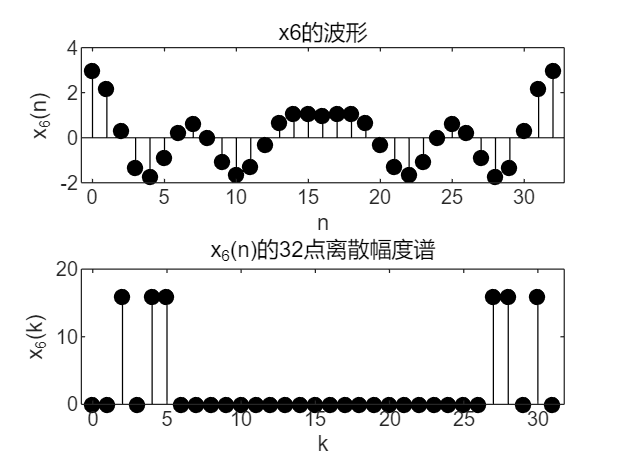

figure();
subplot(211);stem(0:length(xnT2)-1,xnT2,'fill','k');
title('x6的波形'),xlabel('n'),ylabel('x_6(n)');
subplot(212);stem(0:N2-1,abs(xk2),'fill','k');
title('x_6(n)的32点离散幅度谱'); xlabel('k'),ylabel('x_6(k)');

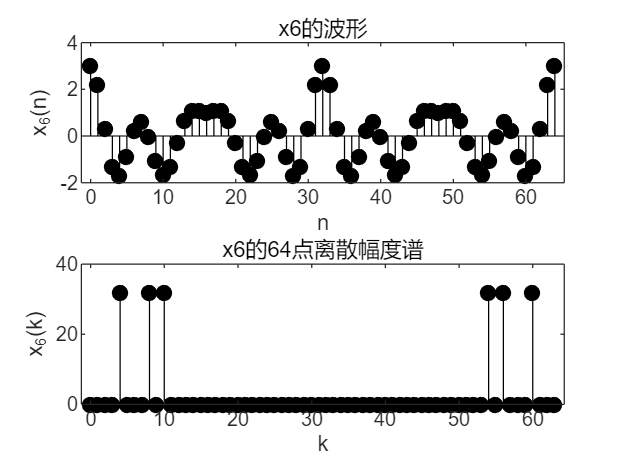

figure();
subplot(211);stem(0:length(xnT)-1,xnT,'fill','k');
title('x6的波形');xlabel('n'),ylabel('x_6(n)');
subplot(212);stem(0:N3-1,abs(xk3),'fill','k');
title('x6的64点离散幅度谱');xlabel('k'),ylabel('x_6(k)');

`对该信号求周期可得`T=32`，所以在`N=16`时，由于不是整数倍的周期，从而导致其`DFT`变换得到的频谱不是`x(n)`的频谱。`

问题五

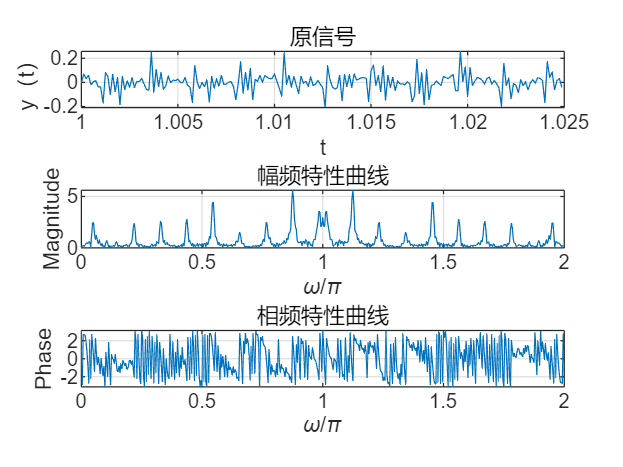

% 从 'motherland.wav' 文件中读取音频数据 y 和采样率 fs
[y, fs] = audioread('motherland.wav');

% 截取 y 信号的第 8000 到 8199 个采样点 (共 200 个点)
y1 = y(8000:8199,1);

% 计算采样周期
ts = 1/fs;
% 创建对应于所截取信号段的时间向量 t
t = 8000/fs:ts:8199/fs;
% 设置 FFT 点数 N=512
N = 512;
% 对 200 点的 y1 进行 512 点 FFT
% (自动在末尾填充 512-200 = 312 个 0)
Y1 = fft(y1,N);

% 创建归一化数字角频率轴 w，范围从 0 到 2*pi
x = 0:2*pi/N:(N-1)*2*pi/N;
% 计算 FFT 结果的幅值
abY = abs(Y1);
% 计算 FFT 结果的相位 (弧度)
angY = angle(Y1);

% --- 4. 绘图 ---
% 将图窗分为 3 行 1 列
% 绘制第 1 个子图：时域波形
subplot(311);plot(t,y(8000:8199)),grid on;
xlabel('t'),ylabel('y（t）');title('原信号');

% 绘制第 2 个子图：幅频特性
% x 轴使用 w/pi (即 x./pi)，范围从 0 到 2
subplot(312);plot(x./pi,abY),grid on;
xlabel('\omega/\pi'),ylabel('Magnitude');title('幅频特性曲线');

% 绘制第 3 个子图：相频特性
% x 轴使用 w/pi
subplot(313);plot(x./pi,angY),grid on;
xlabel('\omega/\pi'),ylabel('Phase');title('相频特性曲线');

问题六

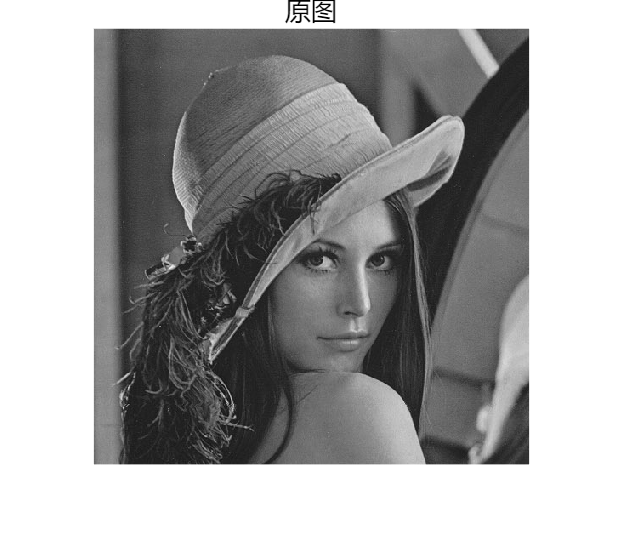

A = imread('lena.bmp');
figure();
imshow(A);title('原图');

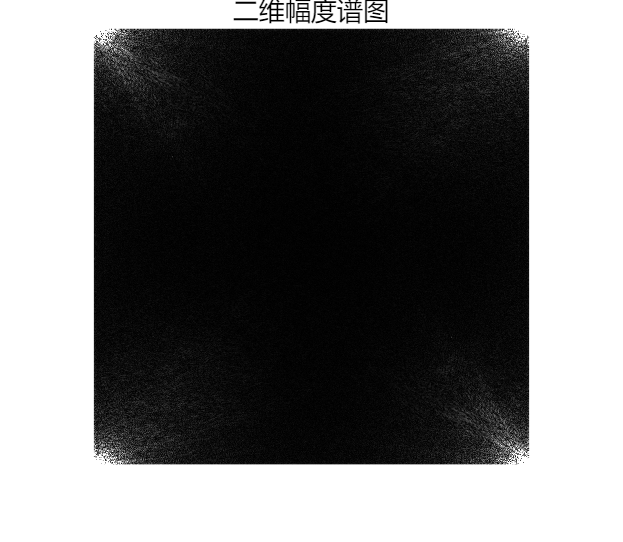

fftI = fft2(A);
A1 = abs(fftI);
B1=(A1-min(min(A1)))/(max(max(A1))-min(min(A1)))*255;
figure();
imshow(B1);title('二维幅度谱图');

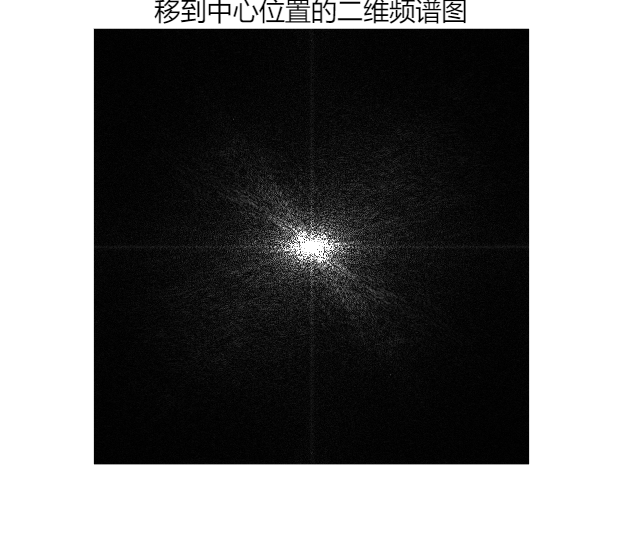

B=fftshift(B1);
figure();
imshow(B);title('移到中心位置的二维频谱图');

频谱图用于展示图像的频率分布，即图像整体特征。频谱图中心为0频率点，表示无灰度变化的部分能量。同心圆的半径和亮度代表频率和能量

全黑图像的频谱图为全黑，表示无能量

灰色图像的频谱图是一个单像素白色方块，能量集中在0频率点上

全白图像的频谱图也是一个单像素白色方块，其能量高于灰色图像，仍集中在0频率点上

这是一个关于傅里叶变换（FFT）在计算机中如何存储和可视化的经典现象。

简单来说，这个现象的根源在于：

- **fft2**** 函数** 默认将其计算结果的“零频率”（DC分量）放在**矩阵的左上角 (1,1)**。

- **fftshift**** 函数** 的作用是**重新排列**这个矩阵，将“零频率”**移动到图像的中心**。

思考题

思考题1

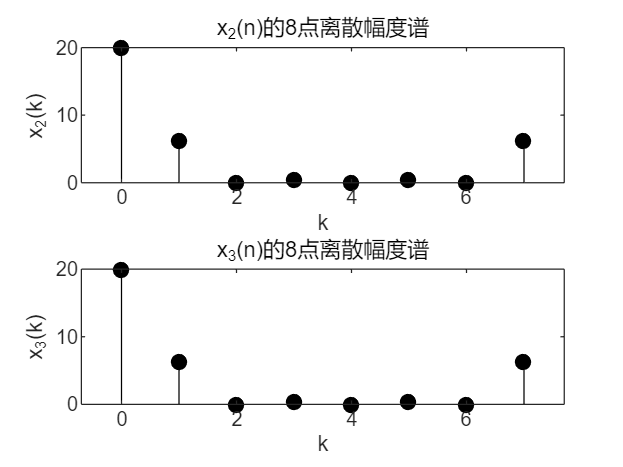

%思考题
x2 = [1,2,3,4,4,3,2,1];
x3 = [4,3,2,1,1,2,3,4];
N1=8;N2=16;
xk2_8=fft(x2,N1);xk2_16=fft(x2,N2);
xk3_8=fft(x3,N1);xk3_16=fft(x3,N2);
figure()
subplot(211);stem(0:N1-1,abs(xk2_8),'fill','k');
title('x_2(n)的8点离散幅度谱');xlabel('k'),ylabel('x_2(k)');
subplot(212);stem(0:N1-1,abs(xk3_8),'fill','k');
title('x_3(n)的8点离散幅度谱');xlabel('k'),ylabel('x_3(k)');

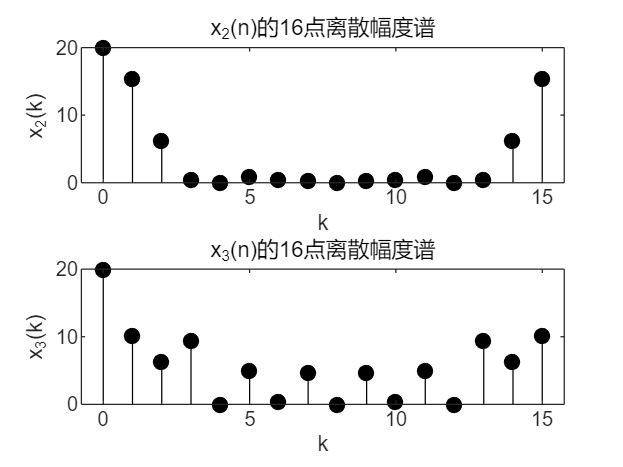

figure()
subplot(211);stem(0:N2-1,abs(xk2_16),'fill','k');
title('x_2(n)的16点离散幅度谱');xlabel('k'),ylabel('x_2(k)'); 
subplot(212);stem(0:N2-1,abs(xk3_16),'fill','k');
title('x_3(n)的16点离散幅度谱');xlabel('k'),ylabel('x_3(k)'); 

当N=8时，x2(n)、x3(n)的幅频特性相同；当N=16时，x2(n)、x3(n)的幅频特性不相同，因为N=16时需要在有限长序列后面补零。

思考题二

`如果周期信号的周期预先不知道，可以先随便截取`N`点进行`DFT`，再用`2N`点进行`DFT`运算，比较结果，如果误差在允许的范围内，则可以近似表示该信号的频谱。如果误差太大换一个`N`值重新截取。`

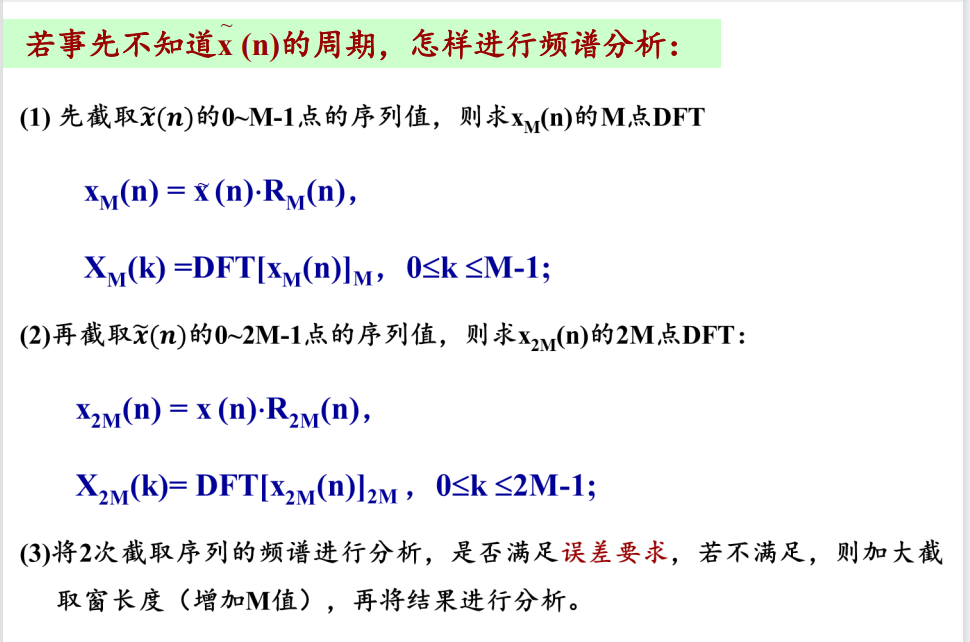

思考题3

x = [1,1,2,2,3,3,2,2,1,1];
x1 = x(1:2:length(x));%压缩
x2 = x(1:0.5:length(x));%拉伸

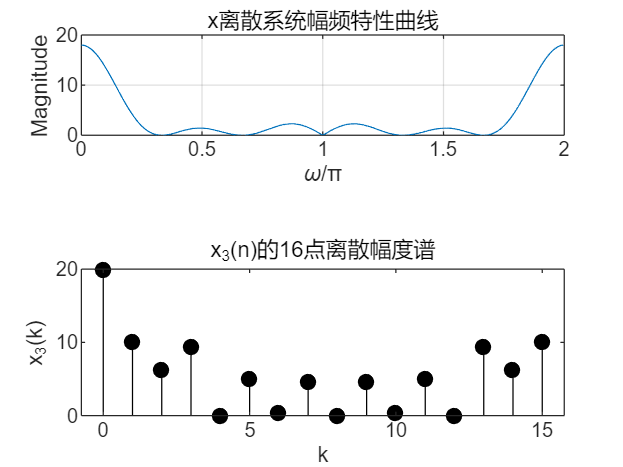

x2(2:2:length(x2)) = 0;
N = 512;
xk = fft(x,N); xk = abs(xk);
xk1 = fft(x1,N); xk1 = abs(xk1);
xk2 = fft(x2,N); xk2 = abs(xk2);
n=0:2*pi/N:(N-1)*2*pi/N;
subplot(311);plot(n./pi,xk),grid on;
xlabel('\omega/π'),ylabel('Magnitude');title('x离散系统幅频特性曲线');

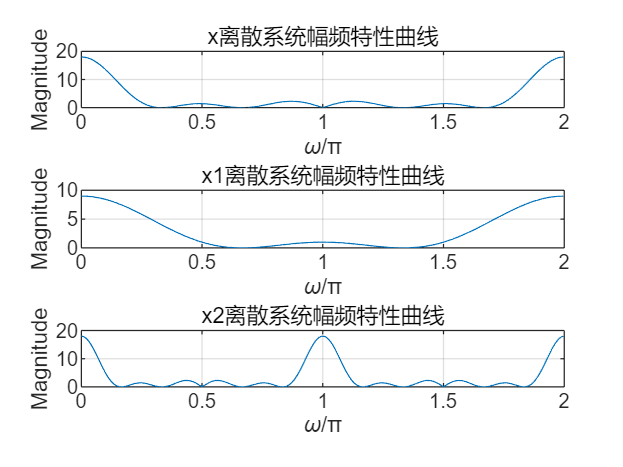

subplot(312);plot(n./pi,xk1),grid on;
xlabel('\omega/π'),ylabel('Magnitude');title('x1离散系统幅频特性曲线');
subplot(313);plot(n./pi,xk2),grid on;
xlabel('\omega/π'),ylabel('Magnitude');title('x2离散系统幅频特性曲线');

从x序列中抽取得到x1序列，由傅里叶变换的尺度压扩特性，x1序列的频谱在[0,2]相对于x序列的频谱是被扩展了2倍，所以频谱图相比x序列显得更加平滑；

从x序列内插得到x2序列，由傅里叶变换的尺度压扩性质，x2序列的频谱在[0,2]相对于X序列的频谱是被压缩了2倍，所以频谱图变化相比x序列来说更加陡峭并且在高频时幅度值达到最大值。